%calculating the mean first passage time using Gillespie simulations 
%investigate effect of invader-substrate mismatches on RNA/DNA TMSD
%kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

g = 2 %define invader toehold length

g = 2


R = 1.987/1000 % universal gas constant in kcal/K/mol

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -1*R*temp

dGrd = -0.5924

dGmm = 3*R*temp

dGmm = 1.7773

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

N = 10 % number of simulations

N = 10

avr_first_pass_time = zeros(1,19)

avr_first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_first_pass_time = zeros(19, N)

ind_first_pass_time =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


k_eff = zeros(1, 19)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_k_eff = zeros(19, N)

ind_k_eff =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


std_err_fpt = zeros(1, 19)

std_err_fpt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_k_eff = zeros(1, 19)

std_err_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_log_k = zeros(1,19)

std_err_log_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through mismatch positions
for m = 1:19
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_Crm = k_bp * exp((dGmm - dGbm + dGrd)/(R*temp)) %I have added + dGrd
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    
    first_pass_time = zeros(1,N)
    
    %create arrays for forward and reverse transition rates
    if g == 1
        Kf = [k_AB1, k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, k_Cr, repmat(k_Cr, [1 b-2]), k_DC]
        Kb(g + m + 1) = k_Crm
        
        %define spontaneous incumbent dissociation rate
        Koff = [0, 0]; 
        for n = b-1:-1:1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [0])
    else
        Kf = [k_AB1, k_BC1ij, repmat(k_BC1ij, [1, g-2]), k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, repmat(k_BC1ji, [1, g-2]), k_BC1ji, k_Cr, repmat(k_Cr, [1, b-2]), k_DC]
        Kb(g + m + 1) = k_Crm
        
        %define spontaneous incumbent dissociation rate
        Koff = [repmat(0, [1, g+1])];
        for n = b-1:-1:1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [0])      
    end
    
    totalrate = Kf + Kb + Koff; %define total rate
    Pf = Kf./totalrate; %define probability of forward transition
    Poff = Koff./totalrate; %define probability of spontaneous incumbent dissociation
    Pb = 1- (Pf + Poff); %define probability of reverse transition 
    %loop through simulations
    for n = 1:N 
        state = 1; %initial state
        t = 0; %initial time
        %restrict to possible states
        while (state >=1 && state < (2 + g + b)) 
            t = t - (1/totalrate(state))*log(rand()); %calculate time for transition
            prob = rand();
            %select transition
            if prob <= Pf(state) 
                state = state +1; %update state forward
            elseif prob > Pf(state) && prob < Pf (state) + Poff(state)
                state = 2 + g + b; %update state for spontaneous incumbent dissociation
            else 
                state = state -1; %update state backwards
            end
        end
        first_pass_time(n) =  t; 
        ind_first_pass_time(m,n) = first_pass_time(n);
        ind_k_eff(m,n) = 1/(first_pass_time(n)*(5*10^-8));
    end
    std_err_fpt(m) = std(ind_first_pass_time(m, :))/sqrt(N); %calculate standard error
    std_err_k_eff(m) = std(ind_k_eff(m, :))/sqrt(N);
    std_err_log_k(m) = std(log10(ind_k_eff(m,:))/sqrt(N));
    avr_first_pass_time(m) = mean(first_pass_time) %calculate average first passage time
    k_eff(m) = 1/(mean(first_pass_time)*(5*10^-8)) %calculate effective rate constant
end

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+03 *

    7.4896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    2.6704         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+03 *

    7.4896    4.5143         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    2.6704    4.4303         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+03 *

    7.4896    4.5143    1.5459         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    0.2670    0.4430    1.2937         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+03 *

    7.4896    4.5143    1.5459    0.8681         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    0.2670    0.4430    1.2937    2.3038         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+03 *

    7.4896    4.5143    1.5459    0.8681    0.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    0.2670    0.4430    1.2937    2.3038    4.0578         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+03 *

    7.4896    4.5143    1.5459    0.8681    0.4929    0.4488         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    0.2670    0.4430    1.2937    2.3038    4.0578    4.4564         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088    0.2778         0         0         0         0         0         0         0         0         0         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919    7.2000         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088    0.2778    0.5939         0         0         0         0         0         0         0         0         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919    7.2000    3.3677         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088    0.2778    0.5939    0.4740         0         0         0         0         0         0         0         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919    7.2000    3.3677    4.2193         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088    0.2778    0.5939    0.4740    0.3792         0         0         0         0         0         0         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919    7.2000    3.3677    4.2193    5.2738         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088    0.2778    0.5939    0.4740    0.3792    0.4392         0         0         0         0         0         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919    7.2000    3.3677    4.2193    5.2738    4.5542         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088    0.2778    0.5939    0.4740    0.3792    0.4392    0.5886         0         0         0         0         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919    7.2000    3.3677    4.2193    5.2738    4.5542    3.3979         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088    0.2778    0.5939    0.4740    0.3792    0.4392    0.5886    0.3146         0         0         0         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919    7.2000    3.3677    4.2193    5.2738    4.5542    3.3979    6.3582         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088    0.2778    0.5939    0.4740    0.3792    0.4392    0.5886    0.3146    0.3977         0         0         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919    7.2000    3.3677    4.2193    5.2738    4.5542    3.3979    6.3582    5.0290         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088    0.2778    0.5939    0.4740    0.3792    0.4392    0.5886    0.3146    0.3977    0.3766         0         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919    7.2000    3.3677    4.2193    5.2738    4.5542    3.3979    6.3582    5.0290    5.3111         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088    0.2778    0.5939    0.4740    0.3792    0.4392    0.5886    0.3146    0.3977    0.3766    0.4402         0


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919    7.2000    3.3677    4.2193    5.2738    4.5542    3.3979    6.3582    5.0290    5.3111    4.5438         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 6.6298e+05

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.6630         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     7.4896    4.5143    1.5459    0.8681    0.4929    0.4488    0.7213    0.4088    0.2778    0.5939    0.4740    0.3792    0.4392    0.5886    0.3146    0.3977    0.3766    0.4402    0.4166


k_eff =     0.2670    0.4430    1.2937    2.3038    4.0578    4.4564    2.7729    4.8919    7.2000    3.3677    4.2193    5.2738    4.5542    3.3979    6.3582    5.0290    5.3111    4.5438    4.8007


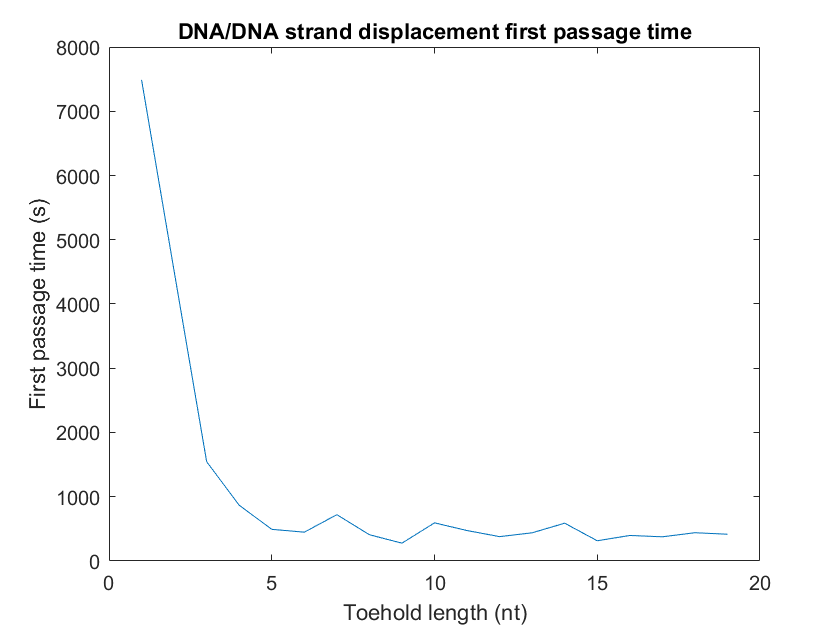

plot(1:19, avr_first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

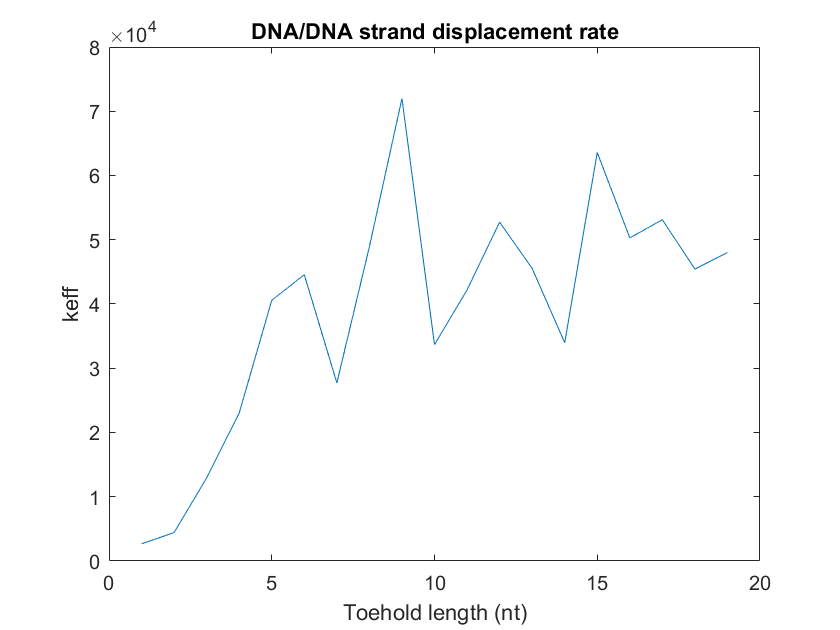


plot(1:19, k_eff)
ylabel('keff')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

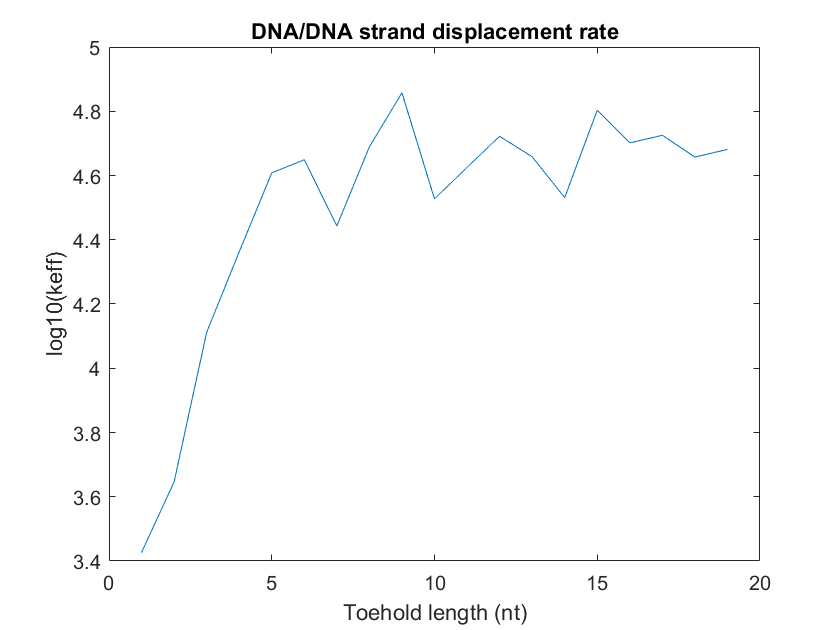


plot(1:19, log10(k_eff))
ylabel('log10(keff)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

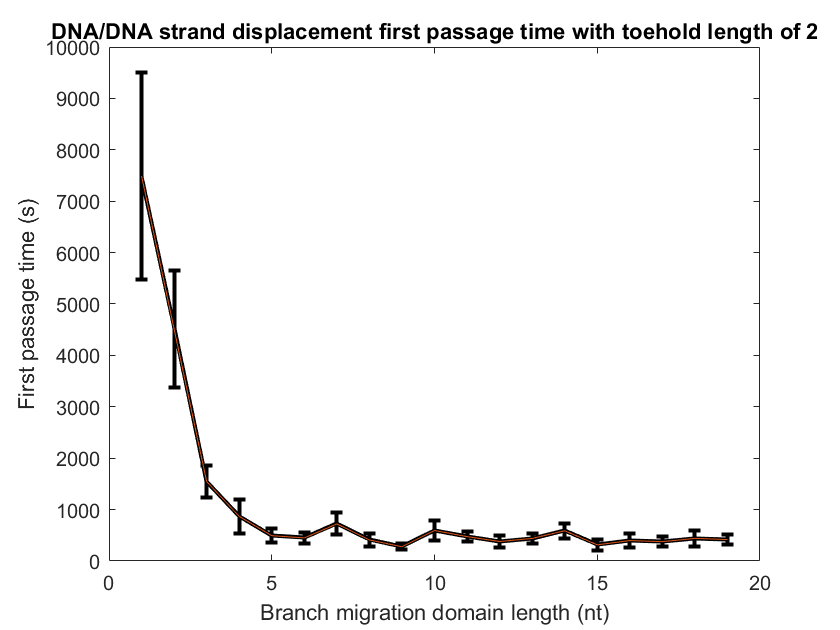


errorbar(1:19, avr_first_pass_time, std_err_fpt , 'k', 'linewidth', 2)
hold on
plot(1:19, avr_first_pass_time, 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('First passage time (s)')
title('DNA/DNA strand displacement first passage time with toehold length of ' + string(g))

hold off

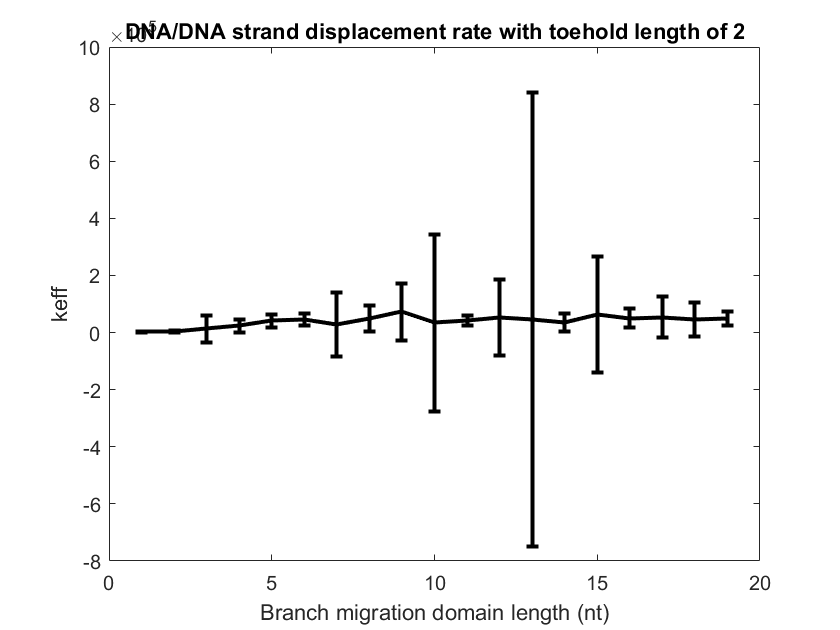


errorbar(1:19, k_eff, std_err_k_eff, 'k', 'linewidth', 2)
xlabel('Branch migration domain length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off

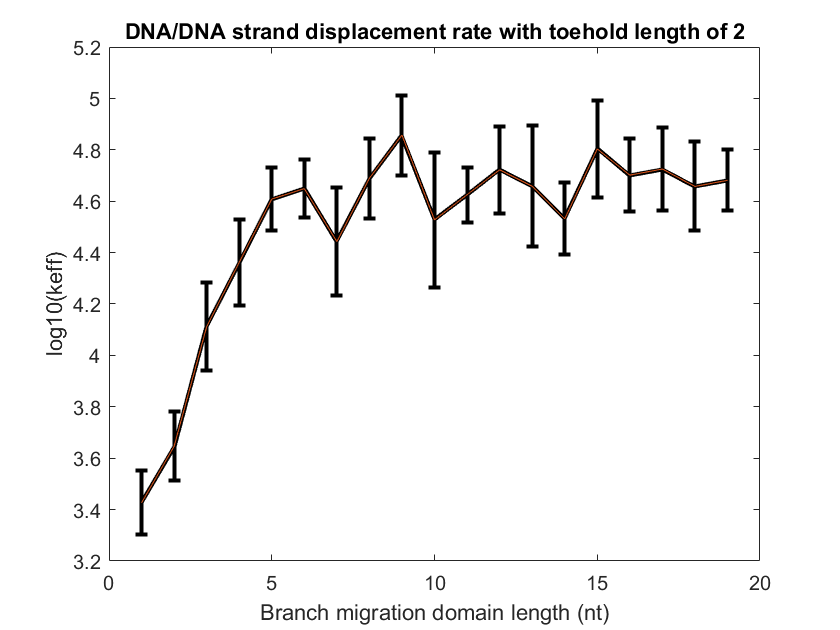


errorbar(1:19, log10(k_eff), std_err_log_k, 'k', 'linewidth', 2)
hold on
plot(1:19, log10(k_eff), '', 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off